# Лабораторная работа №2

# Исследование цепей однофазного синусоидального тока

## Цель работы: 

Получение навыков эксперементального исследования цепей однофазного синусоидального тока.

## Ответы на вопросы подготовки:

### 1)

$I=\frac{U}{Z}$;  $U_R =R*I_R$;    $U_L =i\omega {\mathrm{LI}}_L$;   $U_C =\frac{1}{i\omega C}I_C$

# 1)

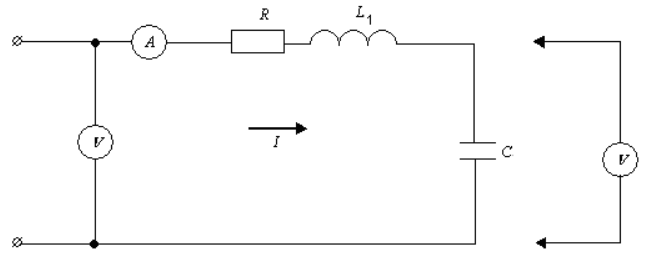

label = {'В';'Гц';'Ом';'Гн';'Ф';'А';'В';'В';'В';'Ом'};
val = [4;1000;51;30e-3;1.2e-6;35.4e-3;1.85;7.96;5.2;1.9];
T = table(label,val,...
    'VariableNames',{'unit','value'},...
    'RowNames',{'U','fi','R','L','C','I','U_r','U_l','U_c','R_l'}...
)

T = 10×2 table
           unit     value 
           ____    _______

    U      'В'           4
    fi     'Гц'       1000
    R      'Ом'         51
    L      'Гн'       0.03
    C      'Ф'     1.2e-06
    I      'А'      0.0354
    U_r    'В'        1.85
    U_l    'В'        7.96
    U_c    'В'         5.2
    R_l    'Ом'        1.9


omeg = T{'fi','value'}*2*pi;
X_C = 1/(omeg*T{'C','value'}*i);
X_L = omeg*T{'L','value'}*i + T{'R_l', 'value'};
X_R = T{'R','value'};
Z = X_C+X_L+X_R

Z = 52.9000 + 55.8664i

I = T{'U','value'}/Z

I = 0.0357 - 0.0378i

U_R = I*X_R;
U_C = I*X_C;
U_L = I*X_L;

#### Мощности:

S_ist = round(I*T{'U','value'},5)

S_ist = 0.1430 - 0.1510i

S_nagr = round(I*(U_R+U_L+U_C),5)

S_nagr = 0.1430 - 0.1510i

#### Погрешности:

d_P = (real(S_ist) - real(S_nagr))/real(S_ist)

d_P = 0

d_Q = (imag(S_ist) - imag(S_nagr))/imag(S_ist)

d_Q = 0

### Проверка 2 закона Киргофа:

round(U_R+U_C+U_L , 5) == T{'U','value'}

ans = logical
   1


Графики:

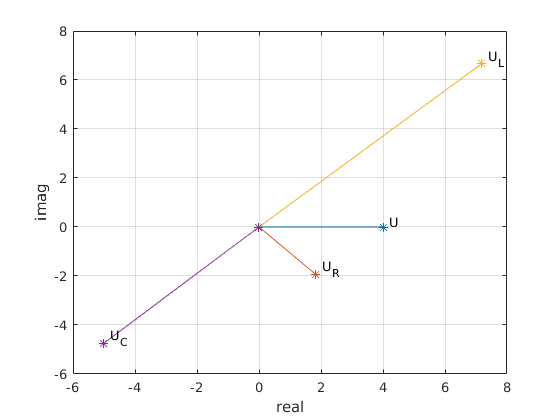

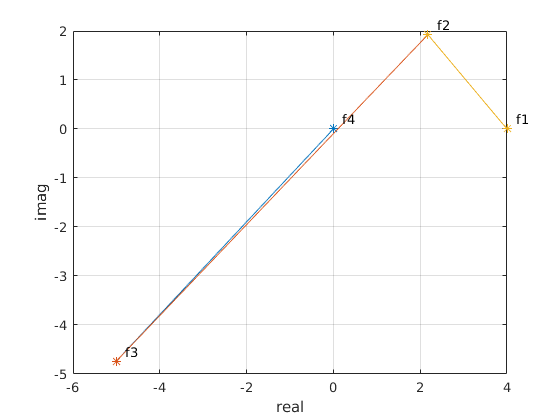

imag2plot({T{'U', 'value'} U_R U_L U_C}, {'U' 'U_R' 'U_L' 'U_C'});

f4 = 0;
f3 = f4 + U_C;
f2 = f3 + U_L;
f1 = f2 + U_R;
f4 = f1 - T{'U','value'};

imag2plot_2({{f4 f3 f2 f1 }}, {{'f4' 'f3' 'f2' 'f1'}});

# 2)

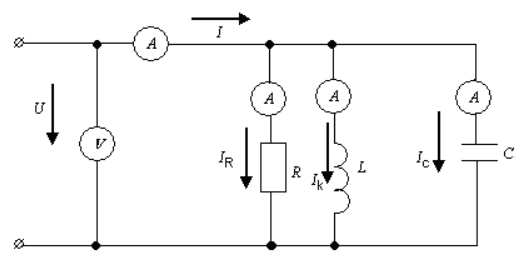

label = {'В';'Гц';'Ом';'Гн';'Ф';'А';'А';'А';'А';'Ом'};
val = [4;1000;51;30e-3;1.2e-6;52.6e-3;52.4e-3;14.5e-3;19.8e-3;1.9];
T = table(label,val,...
    'VariableNames',{'unit','value'},...
    'RowNames',{'U','fi','R','L','C','I','I_r','I_l','I_c','R_l'}...
    )

T = 10×2 table
           unit     value 
           ____    _______

    U      'В'           4
    fi     'Гц'       1000
    R      'Ом'         51
    L      'Гн'       0.03
    C      'Ф'     1.2e-06
    I      'А'      0.0526
    I_r    'А'      0.0524
    I_l    'А'      0.0145
    I_c    'А'      0.0198
    R_l    'Ом'        1.9



omeg = T{'fi','value'}*2*pi;
X_C = 1/(omeg*T{'C','value'}*i);
X_L = omeg*T{'L','value'}*i + T{'R_l','value'};
X_R = T{'R','value'};
Z = (1/X_R + 1/X_L + 1/X_C)^-1

Z = 50.2123 - 5.7084i

Z_12 = (1/X_R + 1/X_L)^-1;
Z_23 = (1/X_L + 1/X_C)^-1;
Z_13 = (1/X_R + 1/X_C)^-1;

I = T{'U','value'}/Z

I = 0.0786 + 0.0089i

I_R = I* Z_23/(Z_23 + X_R);
I_L = I* Z_13/(Z_13 + X_L);
I_C = I* Z_12/(Z_12 + X_C);

#### Мощности:

S_ist = round(I*T{'U','value'},5)

S_ist = 0.3146 + 0.0358i

S_nagr = round(I_R^2*X_R+I_L^2*X_L+I_C^2*X_C,5)

S_nagr = 0.3146 + 0.0358i

#### Погрешности:

d_P = abs((real(S_ist) - real(S_nagr)))/real(S_ist)

d_P = 0

d_Q = abs((imag(S_ist) - imag(S_nagr)))/imag(S_ist)

d_Q = 0

### Проверка 1 закона Кригофа:

round(I_R+I_L+I_C,5) == round(I,5)

ans = logical
   1


#### Графики:

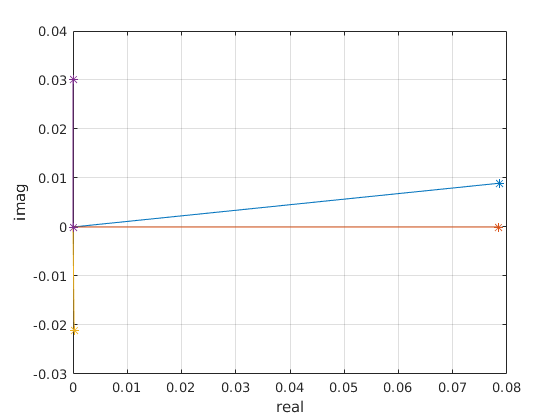

imag2plot({I I_R I_L I_C},{'I' 'I_R' 'I_L' 'I_C'})

# 3)

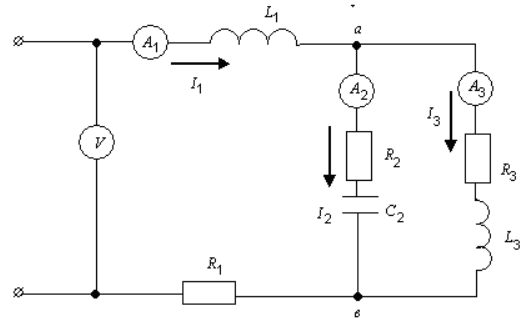

label = {'В';'Гц';'Ом';'Ом';'Ом';'Гн';'Гн';'Ф';'Ом';'Ом';'А';'А';'А';'В';'В';'В';'В';'В';'В'};
val = [4;1000;132.1;51;99.1;10e-3;30e-3;1.2e-6;1.1;1.8;15.5e-3;19.7e-3;13.6e-3;2;1;1.4;1.1;2.7;2.9];
T = table(label,val,...
    'VariableNames',{'unit','value'},...
    'RowNames',{'U','fi','R_1','R_2','R_3','L_1','L_3','C_2','R_L_1','R_L_3','I_1','I_2','I_3','U_R_1','U_R_2','U_R_3','U_L_1','U_L_3','U_C_2'}...
    )

T = 19×2 table
             unit     value 
             ____    _______

    U        'В'           4
    fi       'Гц'       1000
    R_1      'Ом'      132.1
    R_2      'Ом'         51
    R_3      'Ом'       99.1
    L_1      'Гн'       0.01
    L_3      'Гн'       0.03
    C_2      'Ф'     1.2e-06
    R_L_1    'Ом'        1.1
    R_L_3    'Ом'        1.8
    I_1      'А'      0.0155
    I_2      'А'      0.0197
    I_3      'А'      0.0136
    U_R_1    'В'           2
    U_R_2    'В'           1
    U_R_3    'В'         1.4


omeg = T{'fi','value'}*2*pi;
X_R_1 = T{'R_1','value'};
X_R_2 = T{'R_2','value'};
X_R_3 = T{'R_3','value'};
X_L_1 = omeg*T{'L_1','value'}*i + T{'R_L_1', 'value'};
X_L_3 = omeg*T{'L_3','value'}*i + T{'R_L_3', 'value'};
X_C_2 = 1/(omeg*T{'C_2','value'}*i);
Z_2 = X_R_2 + X_C_2;
Z_3 = X_R_3 + X_L_3;
Z_23 = (1/Z_2 + 1/Z_3)^-1;
Z = X_R_1 + Z_23 + X_L_1

Z = 2.9997e+02 - 2.3318e+01i

I = T{'U','value'}/Z

I = 0.0133 + 0.0010i

I_2 = I*Z_3/(Z_3+Z_2)

I_2 = 0.0122 + 0.0127i

I_3 = I*Z_2/(Z_2+Z_3)

I_3 = 0.0011 - 0.0116i

U_R_1 = I*X_R_1;
U_R_2 = I_2*X_R_2;
U_R_3 = I_3*X_R_3;
U_L_1 = I*X_L_1;
U_L_3 = I_3*X_L_3;
U_C_2 = I_2*X_C_2;

#### Мощности:

S_ist = round(I*T{'U','value'},5)

S_ist = 0.0530 + 0.0041i

S_nagr = round(I^2*(X_R_1+X_L_1)+I_2^2*(X_R_2+X_C_2)+I_3^2*(X_R_3+X_L_3),5)

S_nagr = 0.0530 + 0.0041i

#### Погрешности:

d_P = abs((real(S_ist) - real(S_nagr)))/real(S_ist)

d_P = 0

d_Q = abs((imag(S_ist) - imag(S_nagr)))/imag(S_ist)

d_Q = 0

#### Графики:

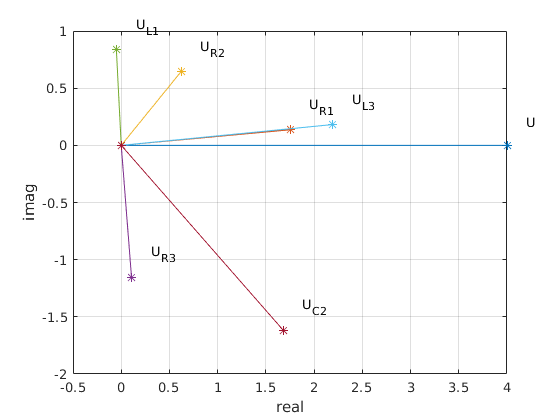

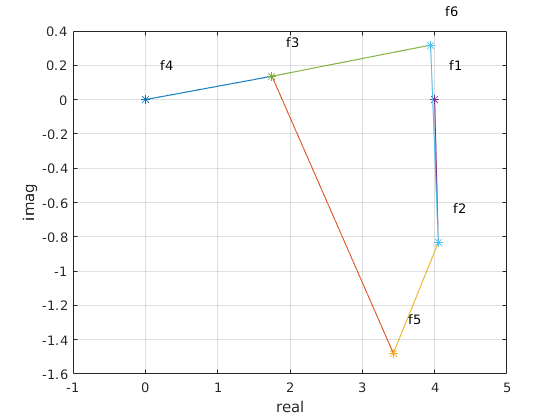

imag2plot({T{'U','value'} U_R_1 U_R_2 U_R_3 U_L_1 U_L_3 U_C_2},{'U' 'U_R_1' 'U_R_2' 'U_R_3' 'U_L_1' 'U_L_3' 'U_C_2'});
f4 = 0;
f3 = f4 + U_R_1;

f5 = f3 + U_C_2;
f2 = f5 + U_R_2;

f6 = f3 + U_L_3;
f2 = f6 + U_R_3;

f1 = f2 + U_L_1;
f4 = f1 - T{'U','value'};

imag2plot_2({{f4 f3 f5 f2 f1} {f3 f6 f2}},{{'f4' 'f3' 'f5' 'f2' 'f1'} {'f3' 'f6' 'f2'}});

## Вывод:

Я получил навыки эксперементального исследования цепей однофазного синусоидального тока.